# **Implementation of Sliding Mode on a Simple Second Order Sys with Parameter Uncertainty and Disturbance**

clear all;close all; clc; format compact; format short; rng(123);

### **System Definition**

            $\ddot{\mathit{\mathbf{x}}} =\mathit{\mathbf{f}}\left(\mathit{\mathbf{x}}\right)+\mathit{\mathbf{u}}+\mathit{\mathbf{d}}$,     $\left|\mathit{\mathbf{f}}-\hat{\mathit{\mathbf{f}}} \right|\;\le \mathit{\mathbf{F}}$,    $\left|\mathit{\mathbf{d}}\right|<\delta$

     where 

                1. $\mathit{\mathbf{f}}\left(\mathit{\mathbf{x}}\right)$ is a vector valued system dynamical function.

                2. $\hat{\mathit{\mathbf{f}}}$ is equal to the middle point of system estimation of system dynamics.

                3. $\mathit{\mathbf{F}}$ is the bounded sysem estimation error function.

                4. $\mathit{\mathbf{d}}$ is a vector valued bounded disturbance function

                5. $\delta$ is the disturbance bound

**    Design:**

            $\mathit{\mathbf{n}}=2$                                                  is the system order

            $\tilde{\mathit{\mathbf{x}}} =\mathit{\mathbf{x}}-{\mathit{\mathbf{x}}}_{\mathit{\mathbf{d}}}$                                          is the tracking error

            $\mathit{\mathbf{s}}={\left(\frac{\mathrm{d}}{\mathrm{d}\mathit{\mathbf{t}}}\;+\lambda \right)}^{\mathit{\mathbf{n}}-1} \tilde{\mathit{\mathbf{x}}} =\dot{\tilde{\mathit{\mathbf{x}}} } +\lambda \tilde{\mathit{\mathbf{x}}}$              is the switching surface

            $\dot{\mathit{\mathbf{s}}} =\dot{\tilde{\mathit{\mathbf{x}}} } +\lambda \tilde{\mathit{\mathbf{x}}} =\ddot{\mathit{\mathbf{x}}} -\ddot{{\mathit{\mathbf{x}}}_{\mathit{\mathbf{d}}} } +\lambda \dot{\tilde{\mathit{\mathbf{x}}} } =0$                                            sliding surface derivative

            ${\mathit{\mathbf{u}}={\mathit{\mathbf{u}}}_{\mathbf{eq}} +\mathit{\mathbf{k}}\;\mathbf{sgn}\left(\mathit{\mathbf{s}}\right)+\delta ,\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\mathit{\mathbf{u}}}_{\mathbf{eq}} =-\hat{\mathit{\mathbf{f}}} +\mathit{\mathbf{d}}+\;\ddot{{\mathit{\mathbf{x}}}_{\mathit{\mathbf{d}}} } -\lambda \dot{\tilde{\mathit{\mathbf{x}}} }$      control signal construction

            given the Lyapunov function $\mathit{\mathbf{V}}=\frac{1}{2}\;{\mathit{\mathbf{s}}}^2$ with setting its derivative to satisfy $\mathit{\mathbf{s}}\dot{\mathit{\mathbf{s}}} \le -\eta \left|\mathit{\mathbf{s}}\right|$, (with $\eta >0$) we have:

                
$$\begin{array}{l}
\mathit{\mathbf{s}}\dot{\mathit{\mathbf{s}}} =\mathit{\mathbf{s}}\;\left(\mathit{\mathbf{f}}+\mathit{\mathbf{u}}+\mathit{\mathbf{d}}-\ddot{{\mathit{\mathbf{x}}}_{\mathit{\mathbf{d}}} } +\lambda \dot{\tilde{\mathit{\mathbf{x}}} } \;\right)\\
\;\;\;\;=\mathit{\mathbf{s}}\;\left(\mathit{\mathbf{f}}-\hat{\mathit{\mathbf{f}}} +\ddot{{\mathit{\mathbf{x}}}_{\mathit{\mathbf{d}}} } -\mathit{\mathbf{k}}\;\mathbf{sgn}\left(\mathit{\mathbf{s}}\right)+\mathit{\mathbf{d}}-\ddot{{\mathit{\mathbf{x}}}_{\mathit{\mathbf{d}}} } +\lambda \dot{\tilde{\mathit{\mathbf{x}}} } \right)\\
\;\;\;\;=\mathit{\mathbf{s}}\left(\mathit{\mathbf{f}}-\hat{\mathit{\mathbf{f}}} +\mathit{\mathbf{d}}\right)-\mathit{\mathbf{s}}\;\mathit{\mathbf{k}}\;\frac{\left|\mathit{\mathbf{s}}\right|}{\mathit{\mathbf{s}}}\\
\;\;\;\;=\mathit{\mathbf{s}}\;\left(\mathit{\mathbf{F}}+\delta \right)-\mathit{\mathbf{k}}\;\left|\mathit{\mathbf{s}}\right|\;\;\le \;\left|\mathit{\mathbf{s}}\right|\left(\;\mathit{\mathbf{F}}+\delta \right)-\mathit{\mathbf{k}}\;\left|\mathit{\mathbf{s}}\right|\\
\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\le -\eta \left|\mathit{\mathbf{s}}\right|
\end{array}$$
                      

**based on this:**           $\;\Rightarrow \;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\mathit{\mathbf{F}}+\delta -\mathit{\mathbf{k}}\le \eta \;\;\;\;\;\;\;\Rightarrow \;\;\;\;\;\;\;\;\;\;\;\;\;\mathit{\mathbf{k}}\ge \;\mathit{\mathbf{F}}+\eta +\delta$ 

### **Sliding Mode Design on an Example System**

            system definition:       $\ddot{\mathit{\mathbf{x}}} ={\mathit{\mathbf{a}}\left(\mathit{\mathbf{t}}\right)\;\mathit{\mathbf{x}}}^2 +\mathit{\mathbf{u}}+\mathit{\mathbf{d}}\left(\mathit{\mathbf{t}}\right)$      with    $1\le \mathit{\mathbf{a}}\left(\mathit{\mathbf{t}}\right)\le 2$   and    $0\le \mathit{\mathbf{d}}\left(\mathit{\mathbf{t}}\right)\le 1$ .

                we can see that $\hat{\mathit{\mathbf{f}}} =1\ldotp 5\;{\mathit{\mathbf{x}}}^2$   and $\mathit{\mathbf{F}}=0\ldotp 5\;{\mathit{\mathbf{x}}}^2$

                    then we can define $\mathit{\mathbf{u}}=-\hat{\mathit{\mathbf{f}}} +\dot{{\mathit{\mathbf{x}}}_{\mathit{\mathbf{d}}} } -\mathit{\mathbf{k}}\;\textrm{sgn}\left(\mathit{\mathbf{s}}\right)$ with $\mathit{\mathbf{k}}=\mathit{\mathbf{F}}+\eta =0\ldotp 5\;{\mathit{\mathbf{x}}}^2 +\eta$  and $\mathit{\mathbf{s}}=\dot{\tilde{\mathit{\mathbf{x}}} } +\lambda \tilde{\mathit{\mathbf{x}}}$

% Design Parameters
Ctrl.Params.eta      =5;        % Controller Eta Param
Ctrl.Params.lambda   =5;        % Controller Lambda Param
Ctrl.Desired.S       = @sin;                             % Desired Trajectory
Ctrl.Desired.dS      = @cos;                             % Desired Trajectory Derivative
Ctrl.Desired.ddS     = @(x) -sin(x);                     % Desired Trajectory 2nd Derivative
Ctrl.System.a        = @(t) 1.5 + 0.5*sin(t);            % System a(t) Param
Ctrl.System.d        = @(t) 0.5 + 0.5*sin(t);            % System a(t) Param


% Solve ODE for the System Output
tSpan = [0, 20];
x0 = rand(1, 2);
[t, x] = ode23(@(t,x) ODE(t, x, Ctrl), tSpan, x0);

% Get the Sliding Surface and the Control Signal
[~, u, s, Traj] = ODE(t, x, Ctrl);


%% ODE Function
function [dx, u, s, Traj] = ODE(t, x, Ctrl)
    % Unpack States
    x1 = x(1);
    x2 = x(2);

    % Calculate Trajectory
    Traj.xd   = Ctrl.Desired.S(t);
    Traj.dxd  = Ctrl.Desired.dS(t);
    Traj.ddxd = Ctrl.Desired.ddS(t);

    % Error Calc
    Err  = x1 - Traj.xd;        % Error
    dErr = x2 - Traj.dxd;       % Error Derivative

    % Switching Surface
    s = dErr + Ctrl.Params.lambda * Err;

    % Control Signal Creation
    f_hat = 1.5 * x1.^2;
    u_eq = -f_hat + Traj.dxd - Ctrl.Params.lambda * dErr;

    F = 0.5 * x1.^2;
    delta = 1;
    k = F + Ctrl.Params.eta + delta;
    u = u_eq - k .* sign(s);

    % State Derivative
    disturbance = Ctrl.System.d(t);
    dx = [x2; Ctrl.System.a(t) .* x1.^2 + u + disturbance];
end

## Plotting

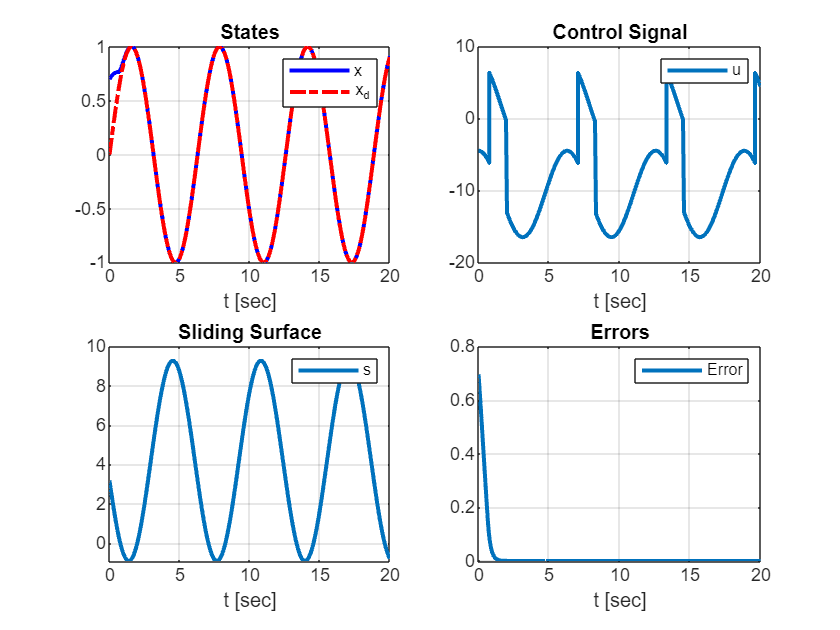

subplot(221)
plot(t, x(:, 1), 'b', t, Traj.xd, 'r-.', 'LineWidth', 2)
grid on, legend('x', 'x_d'), title('States'), xlabel('t [sec]')

subplot(222)
plot(t, u, 'LineWidth', 2)
grid on, legend('u'), title('Control Signal'), xlabel('t [sec]')

subplot(223)
plot(t, s, 'LineWidth', 2)
grid on, legend('s'), title('Sliding Surface'), xlabel('t [sec]')

subplot(224)
plot(t, x(:, 1) - Traj.xd, 'LineWidth', 2)
grid on, legend('Error'), title('Errors'), xlabel('t [sec]')